load cassiniData1.mat

maxRadius = max(Radius)

maxRadius = 9.0400

maxTime = max(Time)

maxTime = 2.0045e+03

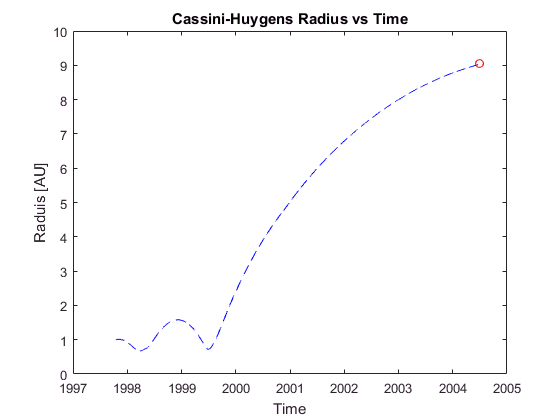


plot(Time, Radius,'--bl')
title('Cassini-Huygens Radius vs Time')
xlabel('Time')
ylabel('Raduis [AU]')
hold on;

plot(maxTime, maxRadius,'o-r')
hold off;

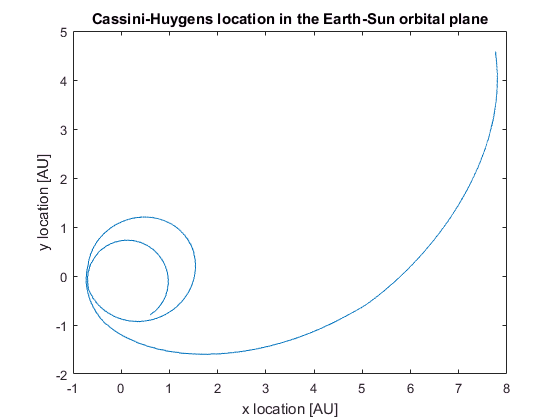


[Rmin,Idx] = min(Radius);
YrSmall = Year(Idx);
MnthSmall = Month(Idx);

Latitude = Latitude * (pi/180);
Longitude = Longitude * (pi/180);

[x,y,z] = sph2cart(Longitude, Latitude, Radius);

plot(x,y)
title('Cassini-Huygens location in the Earth-Sun orbital plane')
xlabel('x location [AU]')
ylabel('y location [AU]')

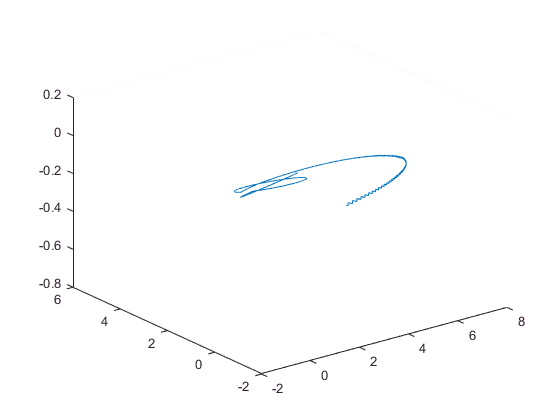


plot3(x,y,z)